## Blind Dereverberation Exploiting the Null of Sylvester Matrix with Group Sparse Regularization in the STFT domain

DIFF: usied analytic signal to determine phase correction

RESULT' not work...

clear

settings

% DGT tool
F = DGTtool("windowLength", 512, "windowShift", 128);

% audio data loading
num_piece = 2;
for i=1:num_piece
    audiofilename = "Goldberg_clav_mono_ds_%d";
    %audiofilename = "9w3r7y_01_%d";
    [temp, fs] =  audioread("input/" + sprintf(audiofilename,i)+".wav");
    ss{i} = temp(:,1);
end
s = [ss{1}; ss{2}];
num_mic = 1;

% ir data loading
[ir, ~] = audioread("BFTLSPACELIBRARY_ChamberAL_11025.wav");
%[ir, fs] = audioread("logic03sWoodenBooth8000.wav");
%[ir{2}, fs(2)] = audioread("../data/BF TL SPACE LIBRARY/Drumbrella/Drumbrella 5'.R.wav");

% ADMM settings
rho = 1.0; % ADMMのペナルティパラメータ (調整用、まずは1.0等から)
alpha = 0.01; % L1正則化の強さ (大きくするほど音漏れがゼロに潰れる)

Malloc

rt = zeros(1,1); % reverb time in sec
obs = cell(1,num_piece); % obs
X = cell(1, num_piece); % STFTs of obs. signal
S = cell(1, num_piece); % STFTs of dry signal
N = zeros(1, num_piece); % length of observation
Lir = zeros(1, 1); % ir length = d + 1
l = zeros(1, num_piece); % length of deconvoluted signal

## resample and shortening

% calculate the reverberation time (RT60)
rt = reverb_time(ir, fs);
ir = ir(1:floor(fs*rt)); ir = ir / norm(ir);
IR = F(ir);
Lir = size(IR, 2);

for j = 1:num_piece
    obs{j} = conv(ss{j}, ir);
    X{j} = F(obs{j});
    N(j) = size(X{j}, 2);
    S{j} = F(ss{j});
end
obsCat = [obs{1}; obs{2}];
D = Lir - 1;
padding = -2;
D = D + padding;
Lir = Lir + padding;

## deconvolution in TF domain

malloc

Fq = size(X{1}, 1);
for i = 1:2, l(i) = N(1, i) - Lir(1) + 1; end
RET1 = zeros(Fq, l(1)); RET2 = zeros(Fq, l(2));
RET1W = zeros(Fq, l(1)); RET2W = zeros(Fq, l(2));
RET_slra = zeros(Fq, sum(l));
% ratio of minimum and the 2nd minimum singular value
singValRatio = zeros(Fq, 1);

% frequency-wise 

時間領域で観測 (x) がクリーン信号 (s) とIR (h) の畳み込みで表されているとする:

$\textrm{Time domain:}~{\bf x} = {\bf s} * {\bf h}$.

それらのDGT (X_f, S_f, H_f) に対して，周波数 f のサブバンドで畳み込みが近似的に成り立っているという立場をとる．


$$\textrm{TF domain}~{\bf X}_f \approx {\bf S}_f * {\bf H}_f
$$


今，独立な二つのクリーン信号 s^1, s^2 があって，同一のIRが畳み込まれたものを観測しているとする:

$\textrm{Time domain} : {\bf x}^{1} = {\bf s}^1 * {\bf h}, {\bf x}^2 = {\bf s}^2* {\bf h}$.

TF領域では，それに対応して


$$\textrm{TF domain} : {\bf X}^{1}_f = {\bf S}^1_f * {\bf H}_f, {\bf X}^2_f = {\bf S}^2_f* {\bf H}_f$$


がある．式をいじって，次を得る:

$\textrm{TF domain} : {\bf X}^{1}_f * {\bf S}_f^2 = {\bf X}^2_f * {\bf S}^1_f,= {\bf S}_f^1*{\bf S}^2_f* {\bf H}_f$.

一つ目の等号の部分から


$$\textrm{TF domain} : {\bf X}^{1}_f * {\bf S}_f^2 - {\bf X}^2_f * {\bf S}^1_f = {\bf 0}$$


これを畳み込み行列を使って表すと，


$$\textrm{TF domain} : \\
{\rm Conv}({\bf X}^{1}_f) {\bf S}_f^2 - {\rm Conv}({\bf X}^2_f) {\bf S}^1_f = {\bf 0}\\ \downarrow\\
\left[{\rm Conv}({\bf X}^{2}_f)  ~{\rm Conv}(-{\bf X}^1_f)\right]
\left[\begin{array}{c}{ {\bf S}^1_f \\{\bf S}_f^2\end{array}\right]= {\bf 0}
$$


（最後に出てきた式の係数行列はSylvester行列と名前がついている）


$${\rm Sylvester} \overset{\rm def}{=} \left[{\rm Conv}({\bf X}^{2}_f)  ~{\rm Conv}(-{\bf X}^1_f)\right]$$


Sylvester行列の零空間の基底ベクトルとしてクリーン信号S_f^1, S_f^2 を獲得する．

TF領域での「近似」畳み込みモデルを使っているので，上記のSylvester行列はフルランク行列になってしまっている，

つまり零空間はないのだが，その代わりに最小特異値に対応する右特異ベクトルを使用してクリーン信号の復元を試みる．

parfor f = 1:Fq
    temp = X{1, 1};  X1f = temp(f, :)';
    temp = X{1, 2};  X2f = temp(f, :)';
    [v1, v2] = sylDerevl21(X1f, X2f, l, rho, alpha);
    RET1(f,:) = v1';   RET2(f,:) = v2';
    % RET1W(f,:) = Vf_w(1:l(1))'; RET2W(f,:) = Vf_w(l(1)+1:end)';
end

### 周波数サブバンドごとに入り込んでるランダムな位相遅延の修復

#### Motivation

畳み込みにおいて，スカラの乗算は畳み込み演算の前後どちらに入れ替えても結合則及び可換則が成立する．


$$\mathbf{x}_f \approx \mathbf{s}_f \ast \hat{\mathbf{h}}_f = (c_f \mathbf{s}_f )\ast (\frac{1}{c_f} \hat{\mathbf{h}}_f)$$


これは、オールパスフィルタがかかっているのとにている。この式からスカラ乗算の不定性を取り除き，真のモデル $\mathbf{x}_f \approx \mathbf{s}_f \ast \mathbf{h}_f$ と一致させるためには，サブバンドIRベクトル $\hat{\mathbf{h}}_f$ に対応する時間領域のRIRに制約（直接音は周波数に関係せず全てのサブバンドで同じ時刻に到達するなどの，現実的に満たすべきものなどが挙げられる）をかけ，制約を満たす位相回転 $c_f$を求める必要がある．位相回転は、時間領域の逆畳み込みでIRを推定し、その位相から計算する。

#### 時間領域での逆畳み込み

時間遅延の統一：各サブバンド $f$ で独立して逆畳み込みを解いた場合，得られるサブバンドIR $\hat{\mathbf{h}}_f$ は，その周波数ビンの中だけで最も辻褄が合うように直接音の到来時刻を推定して，時間遅延をフィットしてしまう．しかし，現実の設定ではすべての周波数成分が同時にマイクに到達するため，全帯域で共通の物理的な時間遅延を持つ．

- サブバンドで個別に解いた場合：サブバンドごとに直接音の立ち上がりタイミングがズレて同定される．

- 時間領域に戻して一括で解いた場合：サブバンドに関係なく全周波数共通で直接音の立ち上がり時刻が強制的に固定され, 周波数間で時間アライメントが揃う

#### IRのフーリエ変換 $H(f)$ とサブバンドIR $\mathbf{h}_f$ の関係

retMid{1} = F.pinv(RET1);   retMid{2} = F.pinv(RET2);
extract_samples_obs = min(22050, length(retMid{1}));
extract_samples = 22050 - length(ir) + 1;
idx_short = 1 : extract_samples_obs;

s1_short = retMid{1}(1:extract_samples);
s2_short = retMid{2}(1:extract_samples);
obs1_short = obs{1}(idx_short);
obs2_short = obs{2}(idx_short);

% 小さなサイズでToeplitz行列を作成 (full size : too large for RAM)
A_time = [convmtx(s1_short, length(ir)); convmtx(s2_short, length(ir))];
b_time = [obs1_short; obs2_short];

% Least-Squares in Time domain with regularization (for robustness)
reg = 1e-4 * max(abs(A_time(:)));
h_time = (A_time' * A_time + reg * eye(size(A_time, 2))) \ (A_time' * b_time);

% h_time 抽出したIR（h_time）をSTFTの窓長に合わせてFFT
H_abs = abs(fft(h_time, F.FFTnum));  H_abs = H_abs(:); % zero-phase signal

% % analytic signal (log-amp being guarded by thresholding)
H_abs(H_abs < 1e-12) = 1e-12;
log_mag = log(H_abs);
analytic = hilbert(log_mag);

% 位相
phase = -imag(analytic);

% 複素スペクトル再構成
H_refined = H_abs .* exp(1j * phase);  % h_min = real(ifft(H));

% For each frequency band, correcting phase rotation
for f = 1:Fq
    if abs(H_refined(f)) > 1e-12
        % obtain phase correct
        phase_correction_f = H_refined(f) / abs(H_refined(f));
        
        % phase correcting
        RET1(f,:) = RET1(f,:) .* conj(phase_correction_f);
        RET2(f,:) = RET2(f,:) .* conj(phase_correction_f);
    end
end

% ⑦ 最終的な残響除去音声の出力
ret{1} = F.pinv(RET1);
ret{2} = F.pinv(RET2);


Display


for i=1:2
    len_ss = length(ss{i});
    len_ret = length(ret{i});
    if len_ss > len_ret
        ss{i} = ss{i}(1:len_ret);
        len_ss = len_ret;
    end
    [SDR,SIR,SAR,perm] = bss_eval_sources(obs{i}(1:len_ss)', ss{i}');
    fprintf("obs: SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(retMid{i}(1:len_ss)', ss{i}');
    fprintf("ret(mid): SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(ret{i}(1:len_ss)', ss{i}');
    fprintf("ret: SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    audiowrite("output/" + sprintf(audiofilename +"_wet.wav", i), obs{i}, fs)
    audiowrite("output/" + sprintf(audiofilename +"_lra_l21_phased_pad=%d.wav", i, padding), ret{i}, fs)
    audiowrite("output/" + sprintf(audiofilename +"_lra_l21_pad=%d.wav", i, padding), retMid{i}, fs)
end

obs: SDR -2.082, SIR Inf, SAR -2.082


ret(mid): SDR 7.167, SIR Inf, SAR 7.167


ret: SDR 6.114, SIR Inf, SAR 6.114


obs: SDR -0.594, SIR Inf, SAR -0.594


ret(mid): SDR 6.784, SIR Inf, SAR 6.784


ret: SDR 6.470, SIR Inf, SAR 6.470


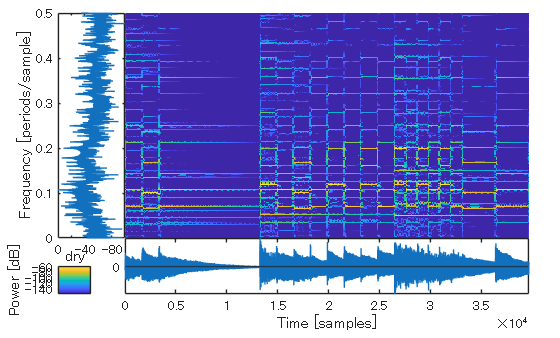


F.plotReassign(ss{1});title("dry"); 
saveas(gcf, "result/" + sprintf(audiofilename,1) + "_dry.png")

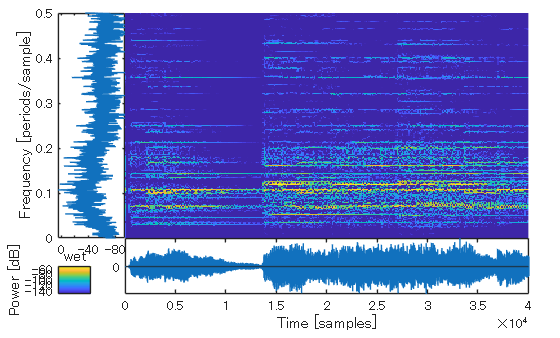

F.plotReassign(obs{1}(1:length(ret{1}))); title("wet"); 
saveas(gcf, "result/" + sprintf(audiofilename,1) + "_wet.png")

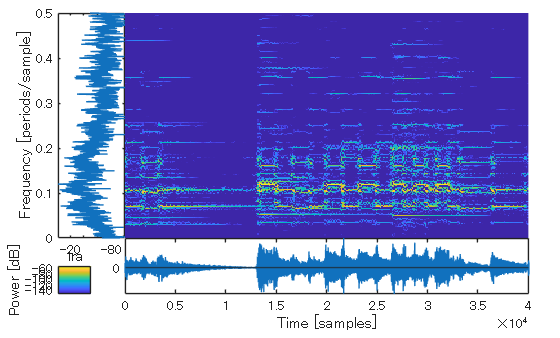

F.plotReassign(retMid{1}); title("lra");
saveas(gcf, "result/" + sprintf(audiofilename + "_ret_pad=%d.png",1, padding) )

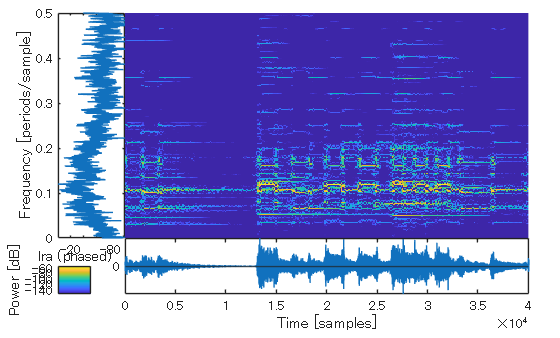

F.plotReassign(ret{1}); title("lra (phased)");
saveas(gcf, "result/" + sprintf(audiofilename + "_ret_phased_pad=%d.png",1, padding) )

- どの結果も時間のマイナス方向に信号が漏れ出ているのがきになる．